# Reto 1

## Restauracion de señales ECG

ECGFile=fopen('ECG/person4/rec_1.dat','r');
ECGData=fread(ECGFile,inf,'*int16');
fclose(ECGFile);
fs=500;
ts=1/fs;
x_r=double(ECGData(1:2:end));
x_f=double(ECGData(2:2:end));
L=length(x_r);
t_r=ts*(0:L-1);
t_f=t_r;

Dibujar señales en el tiempo y frecuencia

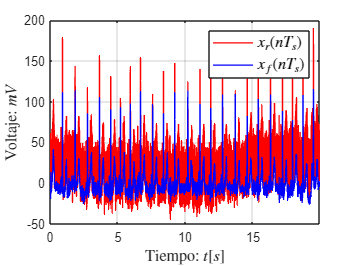

figure;
set(gcf,'Color','w');
plot(t_r,x_r,'r','LineWidth',1.0);
hold on;
plot(t_f,x_f,'b','LineWidth',1.0);
hold off;
grid on;
legend(["$x_{r}(nT_{s})$" "$x_{f}(nT_{s})$"],'FontSize',12,'Interpreter','latex')
xlim([t_r(1) t_r(end)]);
xlabel("Tiempo: $t[s]$",'FontSize',12,'Interpreter','latex')
ylabel("Voltaje: $mV$",'FontSize',12,'Interpreter','latex')

Se identifica una tendencia o **trend**., la señal sube y baja o crece y decrece en todo el rango de tiempo

Se observan patrones de repeticion o **seasonality**. Debido al ciclo cardiaco que es casi periodico

Se distinguen datos atípicos u **outliers**. Variaciones anormales de amplitud en algubos instantes de tiempo que se pueden asociar tambien a ruido impulsivo o a datos faltantes

no se distingue un periodo largo de tiempo o** long-run cycle**, y que no esté relacionado con la seasonality.

No se observan cambios en la varianza

## Analisis en frecuencia

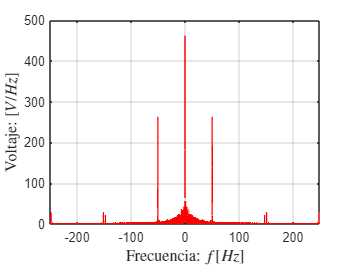

p=nextpow2(L);
K=2^p;
X_r=ts*fftshift(fft(x_r,K));
D=fs/K;
m=-round(K/2):round(K/2)-1;
f=D*m;

figure;
set(gcf,'Color','w');
plot(f,abs(X_r),'r','LineWidth',1.0);
grid on;
%legend(["$x_{r}(nT_{s})$" "$x_{f}(nT_{s})$"],'FontSize',12,'Interpreter','latex')
xlim([f(1) f(end)]);
xlabel("Frecuencia: $f[Hz]$",'FontSize',12,'Interpreter','latex')
ylabel("Voltaje: $[V/Hz]$",'FontSize',12,'Interpreter','latex')

Implementar filtro pasa bajos

filtro muesca en 50 (notch)